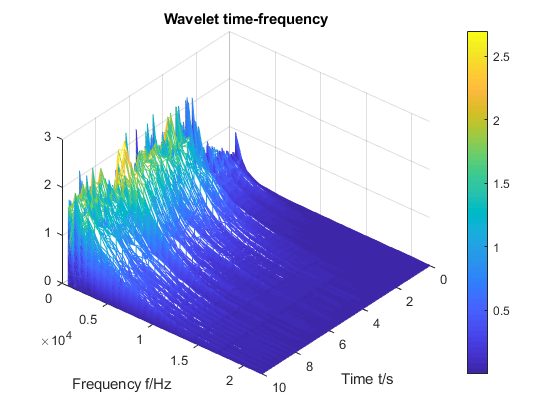

clear;
clc;
[s,fs]=audioread('combined.wav');
FS=length(s); % Length of x;
t=(0:FS-1)*2/fs;
wavename='db3';
totalscal=32; %The total amount of scales
wcf=centfrq(wavename);%Central frequency
cparam=2*wcf*totalscal;%Parament to obtain proper scale
a=totalscal:-1:1;  
scal=cparam./a; 
coefs=cwt(s,scal,wavename); %coefficiency of wavelet
f=scal2frq(scal,wavename,1/fs); %turn scales to frequecies
mesh(t,f,abs(coefs)); %draw 3-D frequency-time figures
colorbar;
xlabel('Time t/s');
ylabel('Frequency f/Hz');
title('Wavelet time-frequency');

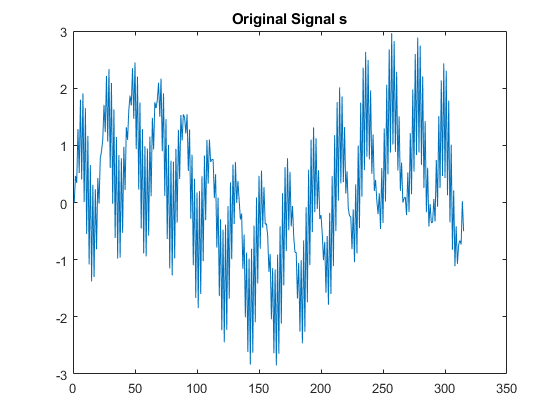


t=0:1:100*pi;
s = sin(3*t) + sin(0.3*t) + sin(0.03*t);
figure(1)
plot(s);
title('Original Signal s');

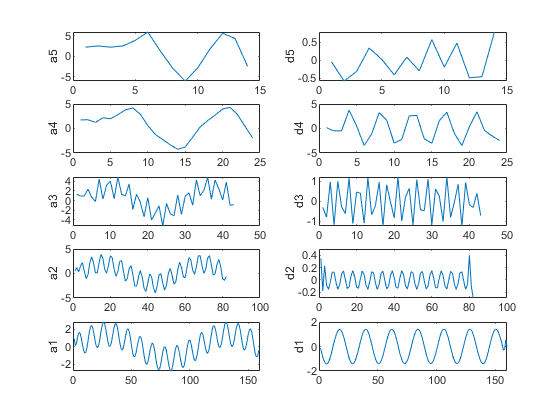

%====================================
%Decompose：db3   level 5
[c,l]=wavedec(s,5,'db3');
%====================================
%Low-frequency parameter
a5=appcoef(c,l,'db3',5);
a4=appcoef(c,l,'db3',4);
a3=appcoef(c,l,'db3',3);
a2=appcoef(c,l,'db3',2);
a1=appcoef(c,l,'db3',1);
%====================================
%High-frequency parameter
d5=detcoef(c,l,5);
d4=detcoef(c,l,4);
d3=detcoef(c,l,3);
d2=detcoef(c,l,2);
d1=detcoef(c,l,1);        
%====================================
figure(2)
subplot(5,2,1);plot(a5);
ylabel('a5');
subplot(5,2,2);plot(d5);
ylabel('d5');
subplot(5,2,3);plot(a4);
ylabel('a4');
subplot(5,2,4);plot(d4);
ylabel('d4');
subplot(5,2,5);plot(a3);
ylabel('a3');
subplot(5,2,6);plot(d3);
ylabel('d3');
subplot(5,2,7);plot(a2);
ylabel('a2');
subplot(5,2,8);plot(d2);
ylabel('d2');
subplot(5,2,9);plot(a1);
ylabel('a1');
subplot(5,2,10);plot(d1);
ylabel('d1');

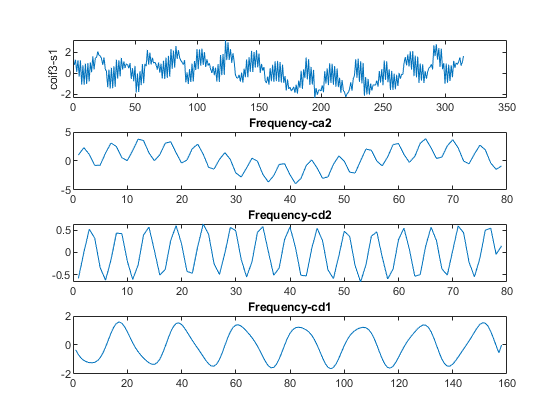

%====================================
%Reconstruct Signal s
s1=waverec(c,l,'db1');
figure(3);
subplot(4,1,1);plot(s1);
ylabel('coif3-s1');


fs1=350;
N=1024;%Samples
n=0:N-1;t=n/fs;
[c,l]=wavedec(s,2,'db1');
ca2=appcoef(c,l,'db1',2);%Extract Low-Frequency Parameter
cd1=detcoef(c,l,1);%Extract High-Frequency Parameter
cd2=detcoef(c,l,2);
subplot(4,1,2);plot(ca2);title('Frequency-ca2');
subplot(4,1,3);plot(cd2);title('Frequency-cd2');
subplot(4,1,4);plot(cd1);title('Frequency-cd1');

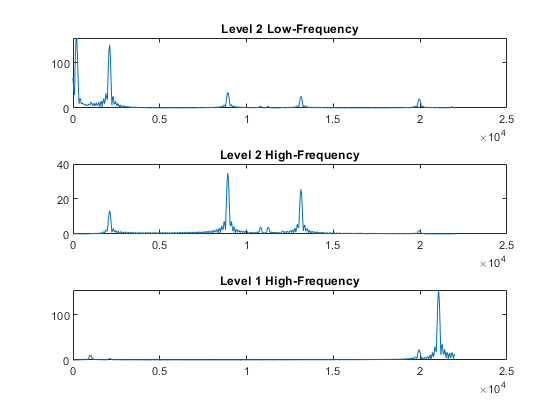

a2=wrcoef('a',c,l,'db1',2);%Low-Frequency Reconstruct
d2=wrcoef('d',c,l,'db1',2);%High-Frequency Reconstruct
d1=wrcoef('d',c,l,'db1',1);
aa2=fft(a2,N);
dd2=fft(d2,N);
dd1=fft(d1,N);
f=n/N*fs;
mag1=abs(aa2);
mag2=abs(dd2);
mag3=abs(dd1);
figure(5)
subplot(3,1,1);plot(f(1:N/2),mag1(1:N/2));title('Level 2 Low-Frequency');
subplot(3,1,2);plot(f(1:N/2),mag2(1:N/2));title('Level 2 High-Frequency');
subplot(3,1,3);plot(f(1:N/2),mag3(1:N/2));title('Level 1 High-Frequency');